## **Dit Dejphachon #6131765321**

## Instructions for Class on 18 February

The zoom meeting is being recorded. The instructor will be present but will not be communicating other than via chat.

You will present your solutions to Homework #3 as usual. Each group will select a question and then present their solution. It is first come, first serve as to which question you want to answer. Each group may only provide the solution to 1 of the questions. It is then up to the other groups not presenting that solution to verify that the solution is correct. If it is incorrect then there should be some discussion about why and how to better understand the mistake or problem. If group 1 is presenting then it is up to group 2 to lead the discussion and ask questions of group 1 as is normally the role of the instructor. If group 5 is presenting then group 1 should lead the discussion. There must be some discussion about each solution. You cannot just present and move on.

The example problems below are not dissimilar to the acoustic wave equation in cartesian coordinates and  shperical coordinates. The problems will give you some basic instruction on solving differential problems using MATLAB. You will then have to do some coding in order to implement the FDM on the different types of equations. You can work in your small groups for the assignment or you can work as a class. Either way, someone needs to drive the discusison. 

## Example Problem 1

Type all of the answers to the questions in this live script. You will submit the live script at the end of the class period.

The deflection *y *in a simply supported beam with a uniform load *q *and a tensile axial load *T *is given by


$$\frac{\partial^2 y}{\partial x^2 }-\frac{T\;y}{E\;I}=\frac{q\;x\left(L-x\right)}{2E\;I}$$
			

where

*x *= location along the beam (in)

*T *= tension applied (lbs)

*E *= Young’s modulus of elasticity of the beam (psi) *I *= second moment of area (in4)

*q *= uniform loading intensity (lb/in)

*L *= length of beam (in)

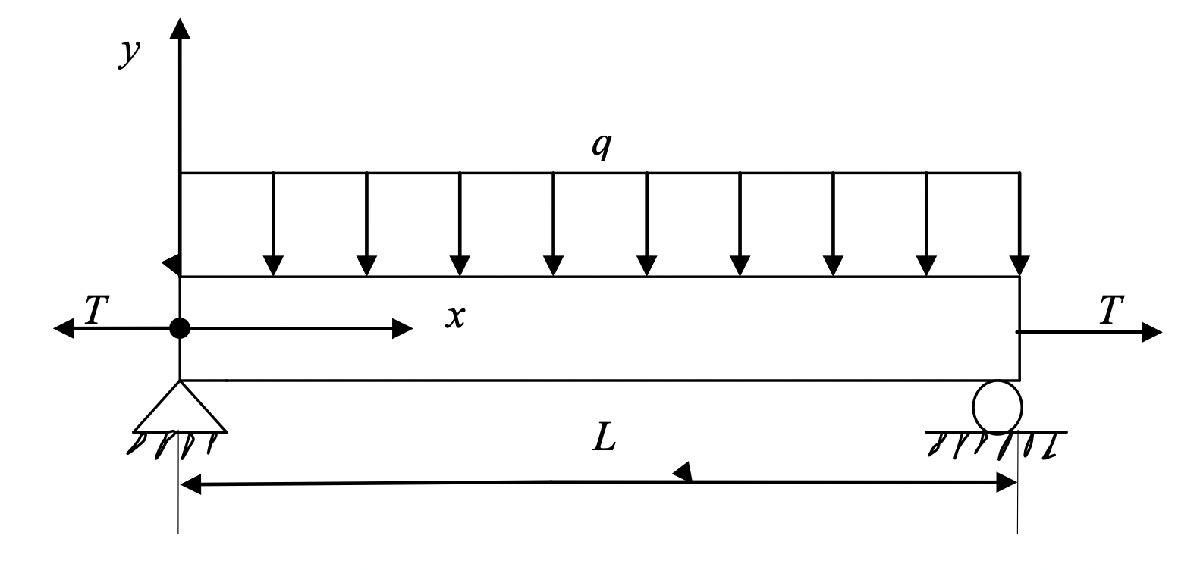

Figure 1. Simply supported beam.				

Given, *T *= 7200 lbs, *q *= 5400 lbs/in, *L *= 75 in, *E *= 30 Msi, and *I *= 120 in^4,

- Find the deflection of the beam at *x *= 50". First do this using the exact solution in MATLAB as outlined in the steps below. You will then develop your own code that will allow you to vary the parameters and determine the deflection

- Using a step size of ∆*x *= 25", approximate the derivatives using the central finite difference

- Using a step size of ∆*x *= 25", approximate the derivatives using the forward finite difference

- Using a step size of ∆*x *= 25", approximate the derivatives using the backward finite difference

- Find the relative true error in the calculation of *y*(50) between the exact solution and the 3 finite difference methods. Which FDM is more accurate? Is this what you expect?

- Decrease the step size by a factor of 2. Repeat your analysis to the question above. What does decreasing the step size by a factor of 2 do to the accuracy of all solutions?

### Exact Solution

Let's use MATLAB to come up with the exact solution to the equation so we can compare the accuracy of our numerical solution.

Let's first define our variables.

T= 7200;
q = 5400;
L = 75;
E = 30 * 10^6;
I = 120;
deltaX = 25;

**FDM - Central**

a = T/(E*I)

a = 2.0000e-06

b = q/(2*E*I)

b = 7.5000e-07



dx=25;
nx = L/dx + 1;

y = zeros(1,nx)

y =      0     0     0     0


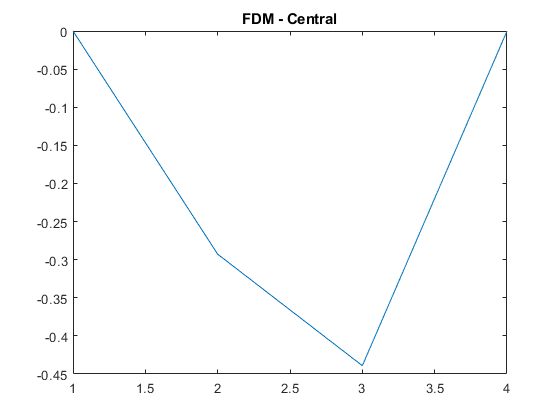

y(1)= 0;
y(nx) = 0;
x = [0:dx:L];
for i = 2:nx-1
   y(i) = -((dx^2)*(b*x(i)*(L-x(i))) - (y(i+1) + y(i-1)))/(2+ a*(dx^2));
end

figure

x= linspace(1,nx,nx);
plot(x,y);
title("FDM - Central")

y(3)

ans = -0.4391

**FDM - backward**

dx=1;
x = [0:dx:L];
nx = L/dx + 1;

y = zeros(1,nx)

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


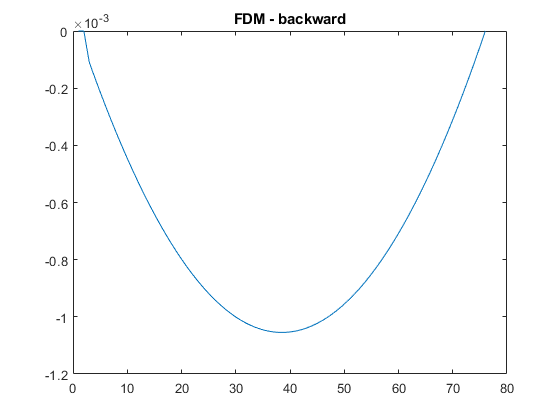

y(1)= 0;
y(nx) = 0;

for i = nx-1:-1:3
    y(i) = -( b*x(i)*(L-x(i))*dx^2 + 2*y(i-1) - y(i - 2) ) / (1 - a*dx^2);
end

figure

x= linspace(1,nx,nx);
plot(x,y);
title("FDM - backward")

y(3)

ans = -1.0950e-04

**FDM - Forward**

dx=0.75;
x = [0:dx:L];
nx = L/dx + 1;

y = zeros(1,nx)

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


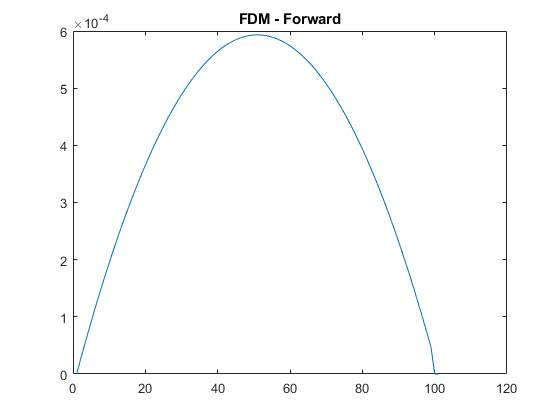

y(1)= 0;
y(nx) = 0;
 
for i = 1:nx-2
   y(i) = (dx^2*b*x(i))*(L-x(i)) - (y(i+2)) + 2*(y(i + 1))/(1 - a*dx^2);

end

figure

x= linspace(1,nx,nx);
plot(x,y);
title("FDM - Forward")

y(3)

ans = 4.6512e-05

First, represent *y* by using `syms` to create the symbolic function `y(t)`.

syms y(x)

Define the equation using `==` and represent differentiation using the `diff` function.

ode = diff(y, x, 2) - T*y/E/I == q*x*(L-x)/2/E/I

$$ode(x) = \frac{\partial^{2}}{\partial x^{2}}y\left(x\right)-\frac{y\left(x\right)}{500000}=-\frac{3\,x\,\left(x-75\right)}{4000000}$$

Define the conditions.

cond1 = y(1) == 0;
cond2 = y(L) == 0;
%cond3 = y(L) == 0;
conds = [cond1 cond2];

Solve the equation using `dsolve and the conditions at the boundaries`.

ySol(x) = dsolve(ode, conds);

Simplify the solution.

ySol = simplify(ySol)

$$ySol(x) = \begin{array}{l} \frac{3\,x^{2}}{8}-\frac{225\,x}{8}-\frac{3\,{\mathrm{e}}^{-\sqrt{2}\,\left(\frac{x}{1000}-\frac{3}{40}\right)}\,\left(499963\,{\mathrm{e}}^{\frac{37\,\sqrt{2}}{500}}-500000\right)}{\sigma_{1}}-\frac{3\,{\mathrm{e}}^{\sqrt{2}\,\left(\frac{x}{1000}-\frac{1}{1000}\right)}\,\left(500000\,{\mathrm{e}}^{\frac{37\,\sqrt{2}}{500}}-499963\right)}{\sigma_{1}}+375000\\ \mathrm{where}\\ \sigma_{1}=4\,\left({\mathrm{e}}^{\frac{37\,\sqrt{2}}{250}}-1\right) \end{array}$$

Substitute in your value for *x* where you want the deflection and get the answer.

x = 50;
double(simplify(subs(ySol)))

ans = -0.5276

## Example Problem 2

Take the case of a pressure vessel that is being tested in the laboratory to check its ability to withstand pressure. For a thick pressure vessel of inner radius *a *and outer radius *b *, the differential equation for the radial displacement *u *of a point along the thickness is given by


$$\frac{\textrm{du}}{dr^2 }+\frac{1}{r}\frac{\textrm{du}}{\textrm{dr}}-\frac{u}{r^2 }=0$$


The inner radius *a *= 5" and the outer radius *b *= 8" , and the material of the pressure vessel is ASTM A36 steel. The yield strength of this type of steel is 36 ksi. Two strain gages that are bonded tangentially at the inner and the outer radius measure normal tangential strain as 	

$\epsilon_{t/r=a}$ = 0.00077462

$\epsilon_{t/r=b}$ = 0.00038462

at the maximum needed pressure. Since the radial displacement and tangential strain are related simply by 		


$$\epsilon_t =\frac{u}{r}$$


then


$$u|_{r=a} =0\ldotp 00077462*5=0\ldotp 0038731"$$



$$u|_{r=b} =0\ldotp 00038462*8=0\ldotp 0030769"$$


The maximum normal stress in the pressure vessel is at the inner radius *r *= *a *and is given by


$$\sigma_{\max } =\frac{E}{1-\nu^2 }\left(\frac{u}{r}|_{r=a} +\nu \;\frac{\textrm{du}}{\textrm{dr}}|_{r=a} \right)$$


where

*E* = Young's modulus of steel (*E *= 30 Msi)

$\nu \;$ = Poisson’s ratio ($\nu \;$= 0.3)

The factor of safety, FS is given by


$$\textrm{FS}=\frac{\textrm{yield}\;\textrm{strength}\;\textrm{of}\;\textrm{steel}}{\sigma_{\max } }$$
		

- Use what you learned above to find the exact solution in MATLAB. You will then develop your own code that will allow you to vary the parameters and determine the deflection

- Using the most accurate FDM that you found in Problem 1, write a MATLAB code that will allow you to specify the number of nodes and will output the radial displacement profile

- Find the maximum normal stress and factor of safety as given by the equation for factor of safety above

- Calculate the relative true error

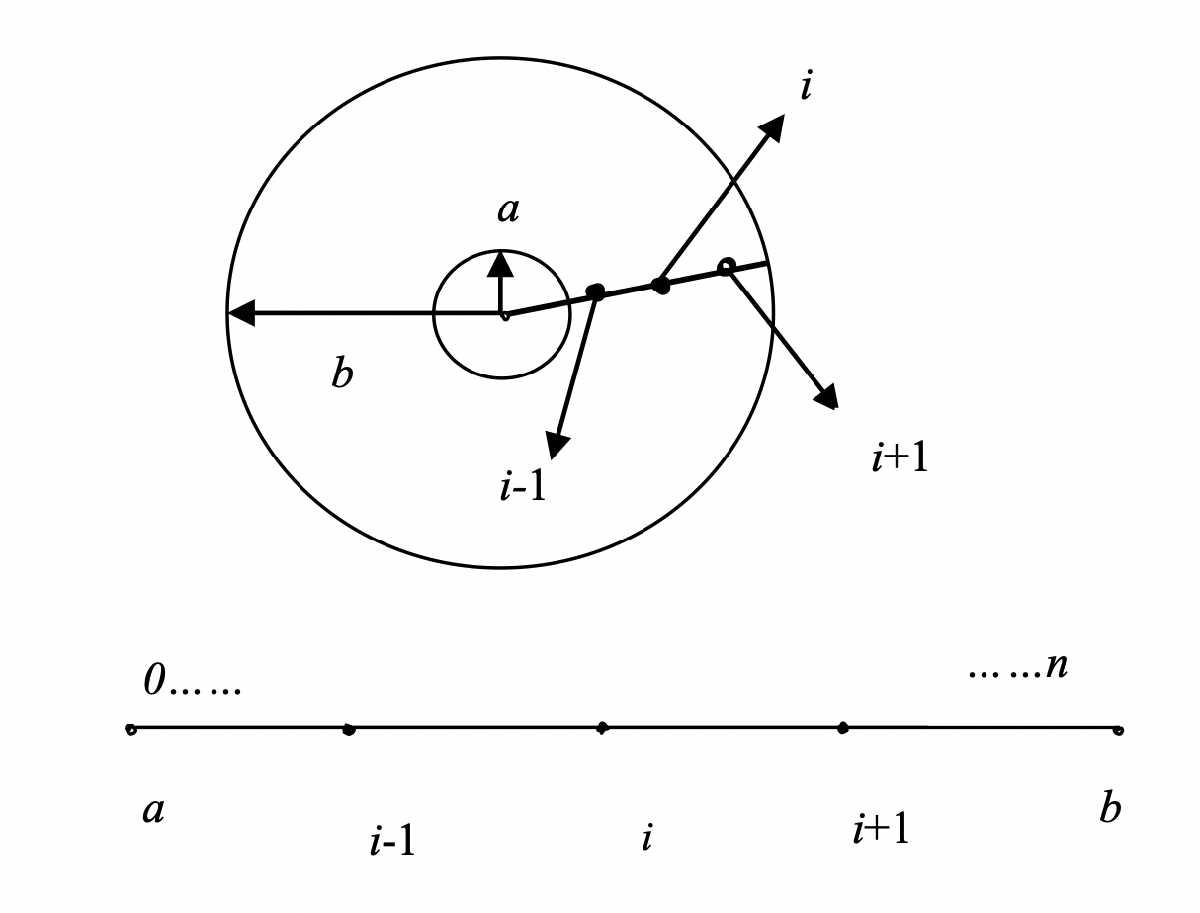

Figure 2. Nodes along the radial direction.